clear all
close all

## 1. Входные данные

Длина волны 

f = 400*10^6;
c = 3*10^8;
lambda = c/f; % 0.75 м

% /1000/lambda % перевод мм в м + в дилнаях волн

Построение графика несущей опоры 

% входные параметры
angle = 65;
l1 = 22017/1000/lambda; % длина участка 1
b = 6992/1000/lambda;
k = 4457/1000/lambda;
% h = 19991; % примем его не верным и зададимся только l1
h = l1*sind(angle);


#### Расчет координат точек

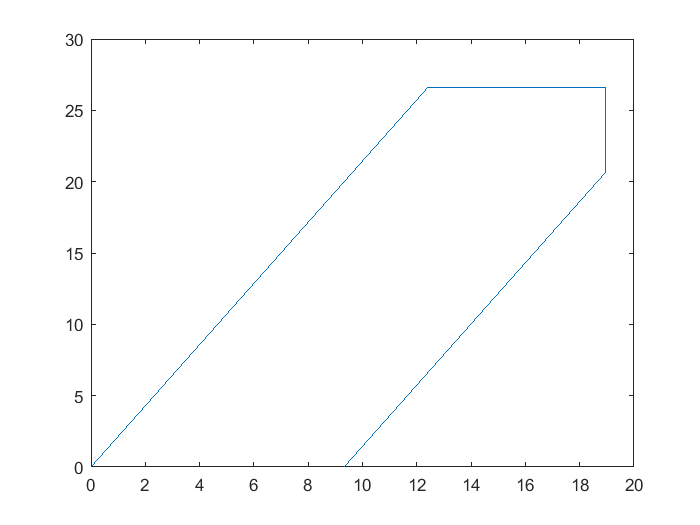

% чтоб изменить высоту антены нужно зименить размер l1
% l1 = ((h - 4457)/tand(angle) + b)/cosd(angle)*15/16; 


x_point_1 = 0;
z_point_1 = 0;

x_point_2 = l1*cosd(angle);
z_point_2 = l1*sind(angle);

z_point_4 = h - k;
x_point_4 = z_point_4/tand(angle) + b;

z_point_3 = z_point_2;
x_point_3 = x_point_4;

x_point_5 = b;
z_point_5 = 0;

X_point = horzcat(x_point_1, x_point_2, x_point_3, x_point_4, x_point_5);
Z_point = horzcat(z_point_1, z_point_2, z_point_3, z_point_4, z_point_5);

plot(X_point, Z_point)

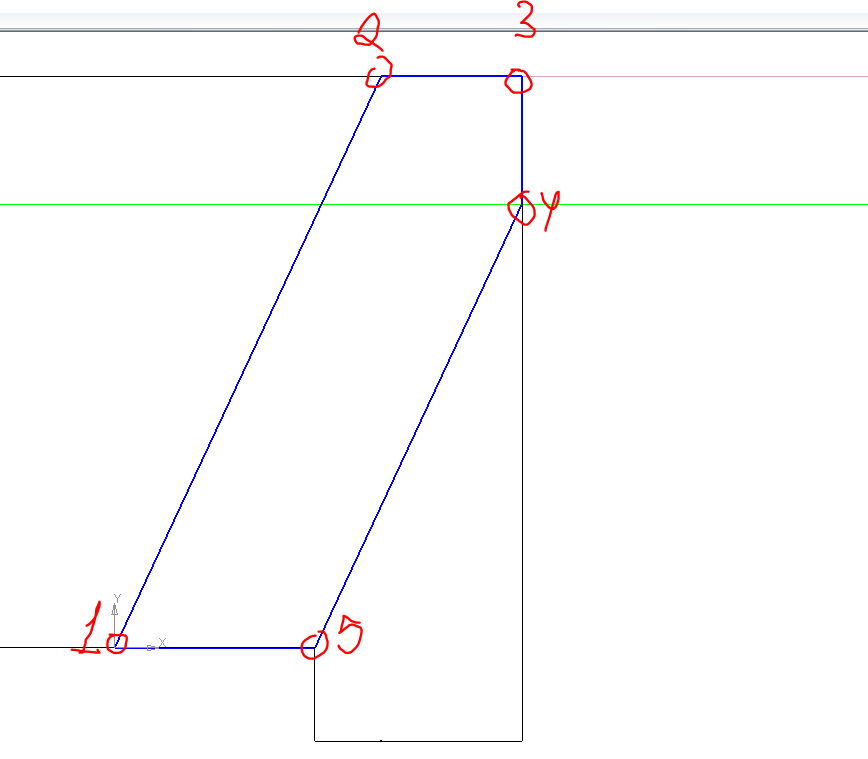

Координаты излучателя

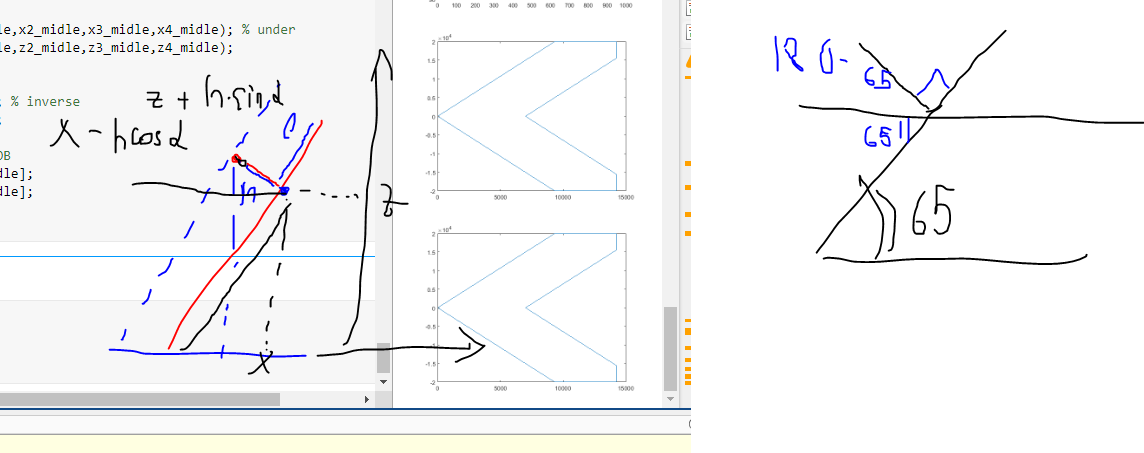

% паарметры расположения
l_antenn = 5/lambda; % от верхнего края наклонной линии
h_antenn = lambda/2; % перпенидкуляр от наклонной линии
angle2 = 90-angle; % угол между перпендик и осью х

% координаты точки на наклонной лини 
x_temp = (l1-l_antenn)*cosd(angle);
z_temp = (l1-l_antenn)*sind(angle);

% координаты самого излучателя
x1_antenn = x_temp - h_antenn*cosd(angle2);
z1_antenn = z_temp + h_antenn*sind(angle2);

x2_antenn = x1_antenn;
z2_antenn = -z1_antenn;

## 3. Построение границ отрезков

#### 3.1 Антена над землей

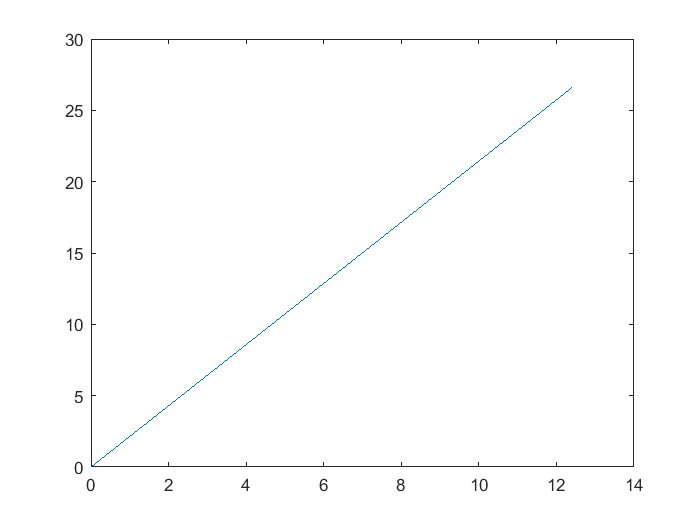

%% УЧАСТОК_1 - наклонный участок

% расчет шага 
l12 = l1;
% N12 = 100; % количество точек не участке 1
% dx_12 = l12/N12;
N12 =  round(l12*100,-1);
dx_12 = l12/N12;

% заполнение масивов
for i = 1 : N12
    step12 = dx_12*i;
    x1(i) = cosd(angle)*step12;
    z1(i) = sind(angle)*step12;
    dx1(i) = dx_12;
end


% график
plot(x1, z1)

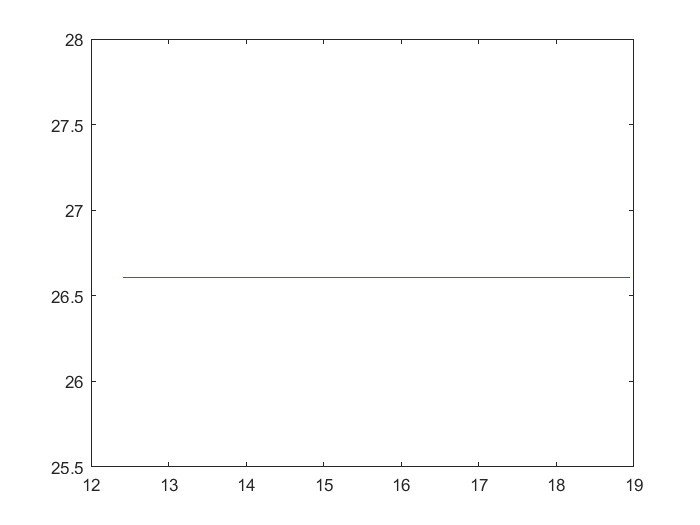

% УЧАСТОК 2 - горизонтальный участок

% расчет шага 
l23 = sqrt((x_point_2 - x_point_3)^2 + (z_point_2 - z_point_3)^2);
% N23 = 100;
% dx_23 = l23/N23;
N23 =  round(l23*100,-1);
dx_23 = l23/N23;

% заполнение масивов
for i = 1 : N23
    step23 = dx_23*i;
    x2(i) = x_point_2 + step23;
    z2(i) = z_point_2;
    dx2(i) = dx_23;
end

% временная шутка для построения графика
if l23 < 10^(-6)
    x2 = x_point_3;
    z2 = z_point_3
end
plot(x2, z2)

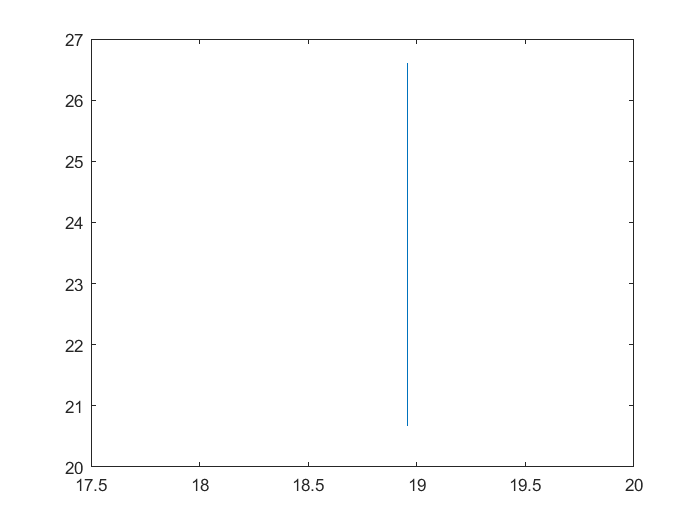

% УЧАСТОК 3 - вниз

% расчет шага 
l34 = sqrt((x_point_4 - x_point_3)^2 + (z_point_4 - z_point_3)^2);
% N34 = 100;
% dx_34 = l34/N34;
N34 =  round(l34*100,-1);
dx_34 = l34/N34;

for i = 1 : N34
    step34 = dx_34*i;
    x3(i) = x_point_3;
    z3(i) = z_point_3 - step34;
    dx3(i) = dx_34;
end

plot(x3, z3);

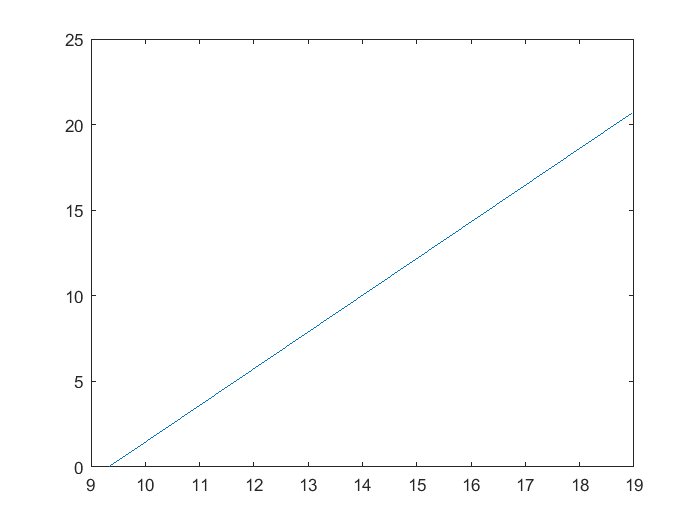

% УЧАСТОК 4 - наклон вниз
l45 = sqrt((x_point_5 - x_point_4)^2 + (z_point_5 - z_point_4)^2);
% N45 = 100;
% dx_45 = l45/N45;
N45 =  round(l45*100,-1);
dx_45 = l45/N45;

for i = 1 : N45 
    step45 = dx_45*i;
    x4(i) = x_point_4 - step45*cosd(angle);
    z4(i) = z_point_4 - step45*sind(angle);
    dx4(i) = dx_45;
end

plot(x4, z4);

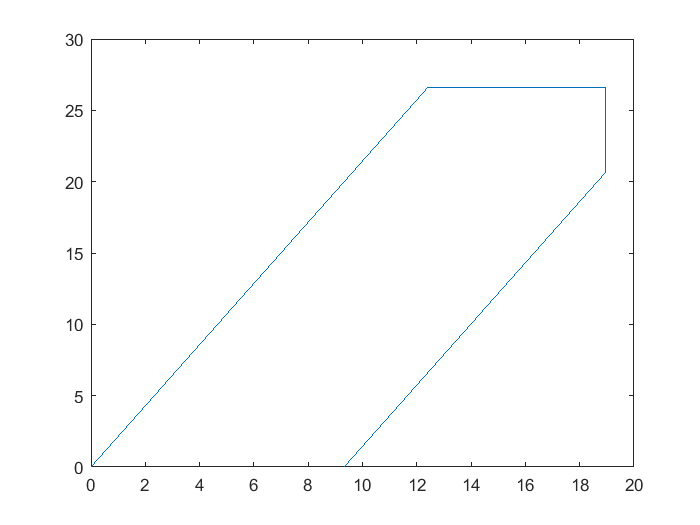

% cклеим все вместе 
X = horzcat(x1,x2,x3,x4);
Z = horzcat(z1,z2,z3,z4);
plot(X,Z)

#### 3.2 Вторая часть антенны (под землей)

xi_point_1 = x_point_1;
zi_point_1 = -z_point_1;

xi_point_2 = x_point_2;
zi_point_2 = -z_point_2;

xi_point_3 = x_point_3;
zi_point_3 = -z_point_3;

xi_point_4 = x_point_4;
zi_point_4 = -z_point_4;

xi_point_5 = x_point_5;
zi_point_5 = -z_point_5;

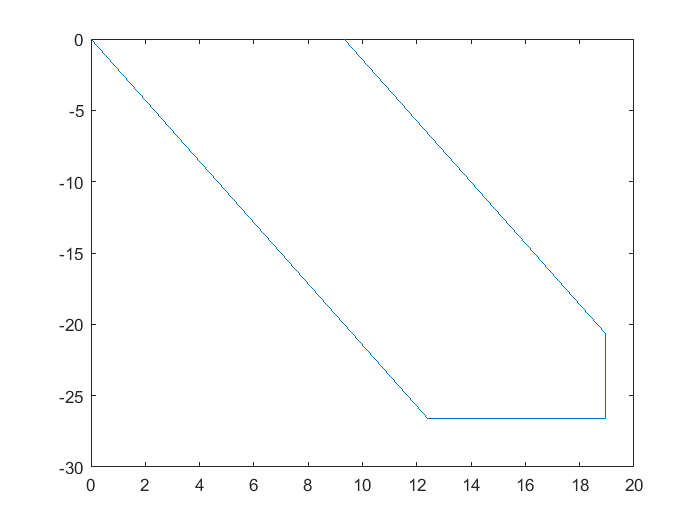

Xi_point = horzcat(xi_point_1, xi_point_2, xi_point_3, xi_point_4, xi_point_5);
Zi_point = horzcat(zi_point_1, zi_point_2, zi_point_3, zi_point_4, zi_point_5);

plot(Xi_point, Zi_point)

#### 3.3 Все антена (границы участков)

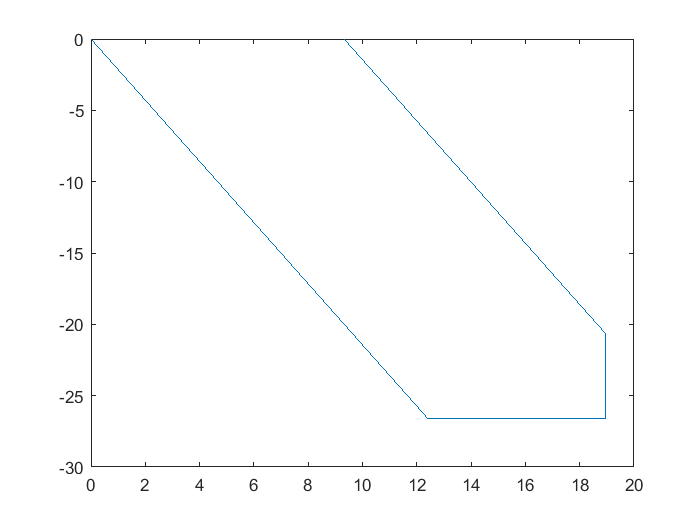

% границы участков
Xi = flip(horzcat(x1,x2,x3,x4));
Zi = flip(horzcat(-z1,-z2,-z3,-z4));

% график всей антенны (границ участков)
plot(Xi,Zi)

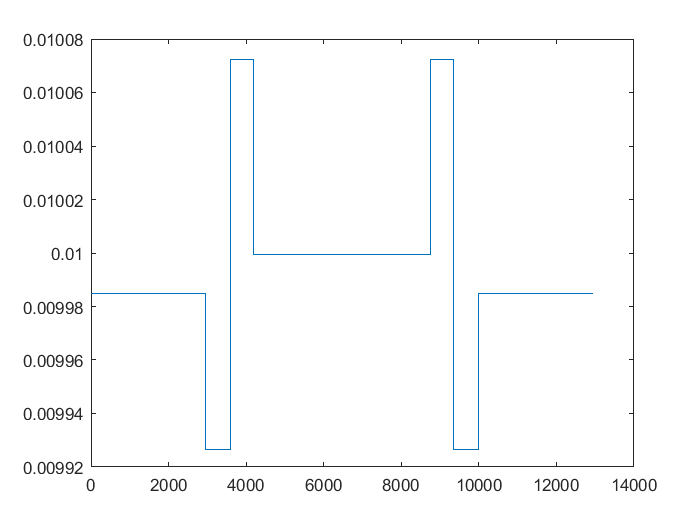

% длины отрезков для каждого участка 
dx_mass = horzcat(dx1,dx2,dx3,dx4,dx4,dx3,dx2,dx1);

% распределение длин отрезков разбиения по антене
plot(1:length(dx_mass), dx_mass);

% cуммареное количество точек на антенне
N = 2*(N12 + N23 + N34 + N45);

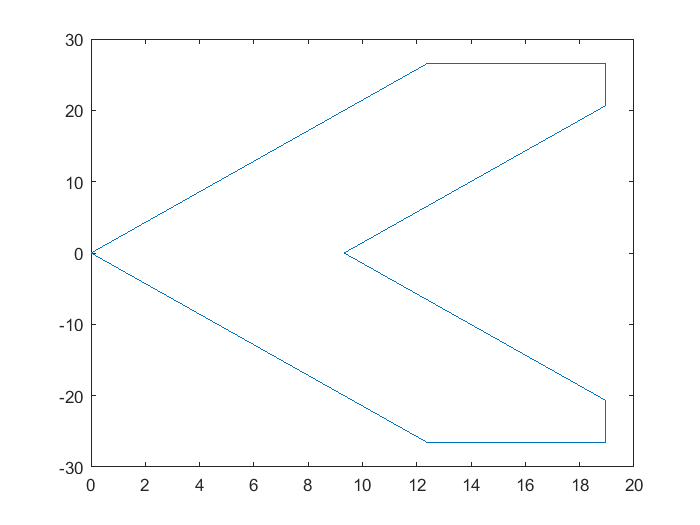

% границы участков, склееные под землей и над землей.
x_border = [X,Xi];
z_border = [Z,Zi];

plot(x_border,z_border)

## 4. Касательные и нормали к отрезкам и центры отрезков

#### 4.1 Точки разрыва границ 


% количество точек на каждом участке привязанная к номерам участка
% (индексам массива)
number_point_N = [N12,N23,N34,N45,N45,N34,N23,N12]; 

sum_var = 0;
for i = 1 : length(number_point_N)
    sum_var = sum_var + number_point_N(i);
    N_break(i) = sum_var;   
end

#### 4.2. Посчитаем t для каждого отрезка

for i = 1 : N
    dx = dx_mass(i);
    if ismember(i, N_break) % проверка принадлежности массиву
        tx(i) = ((x_border(i)-x_border(i-1)))/dx;
        tz(i) = ((z_border(i)-z_border(i-1)))/dx;
    else
        tx(i) = (x_border(i+1)-x_border(i))/dx;
        tz(i) = (z_border(i+1)-z_border(i))/dx;
    end
end

#### 4.3. Посчитаем n для каждого отрезка

%  Посчитаем n для каждого отрезка
%  нормальный вектор найдем с помощью матрицы повороты
    alpha = -90;
    matrix = [cosd(alpha),-sind(alpha); sind(alpha),cosd(alpha)];

for i = 1 : N
     matrix_temp = [tx(i), tz(i)]*matrix;
     nx(i) = matrix_temp(1);
     nz(i) = matrix_temp(2);
end

#### 4.1 Центры участков

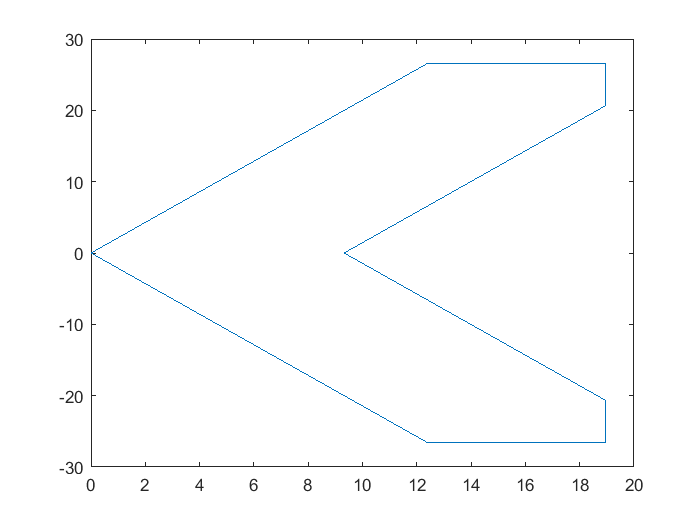

% КООРДИНАТЫ ЦЕНТРОВ ОТРЕЗКОВ
%% УЧАСТОК_1
for i = 1 : N12
    step12 = dx_12*(i-0.5);
    x1_midle(i) = cosd(angle)*step12;
    z1_midle(i) = sind(angle)*step12;
end

% УЧАСТОК 2
% заполнение масивов
for i = 1 : N23
    step23 = dx_23*(i-0.5);
    x2_midle(i) = x_point_2 + step23;
    z2_midle(i) = z_point_2;
end

% УЧАСТОК 3
for i = 1 : N34
    step34 = dx_34*(i-0.5);
    x3_midle(i) = x_point_3;
    z3_midle(i) = z_point_3 - step34;
end

for i = 1 : N45 
    step45 = dx_45*(i-0.5);
    x4_midle(i) = x_point_4 - step45*cosd(angle);
    z4_midle(i) = z_point_4 - step45*sind(angle);
end

% УЧАСТЕК НАД ЗЕМЛЕЙ
Xu_midle = horzcat(x1_midle,x2_midle,x3_midle,x4_midle); % under
Zu_midle = horzcat(z1_midle,z2_midle,z3_midle,z4_midle);

% УЧАСТОК ПОД ЗЕМЛЕЙ
Xi_midle = flip(Xu_midle); % inverse
Zi_midle= flip(-Zu_midle);

% ФИНАЛЬНЫЕ ЦЕНТРЫ УЧАСТКОВ
x_midle = [Xu_midle,Xi_midle];
z_midle = [Zu_midle,Zi_midle];

plot(x_midle, z_midle);

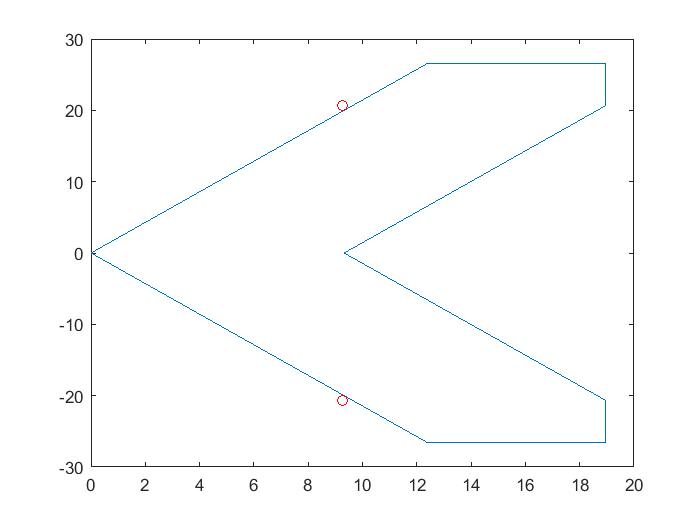

% график антенны с излучателями
plot(x_midle,z_midle,x1_antenn,z1_antenn, '-ro', x2_antenn, z2_antenn, '-ro');

% % нормаль в точек расположения излучателя
% x0 = x_temp;
% z0 = z_temp;
% 
% for i = 1 : 3000
%     x = x0 - i;
%     x_norm(i) = x;
%     z_norm(i) = z0 - 1/tand(angle)*(x-x0);
% end
% 
% plot(x_norm, z_norm)
% 
% plot(x_midle,z_midle,x0,z0, '-o', x_norm, z_norm,'r', x_antenn, z_antenn, 'o')
% 
% xlim([-20000 20000])
% ylim([-20000 20000])

Расчет полей

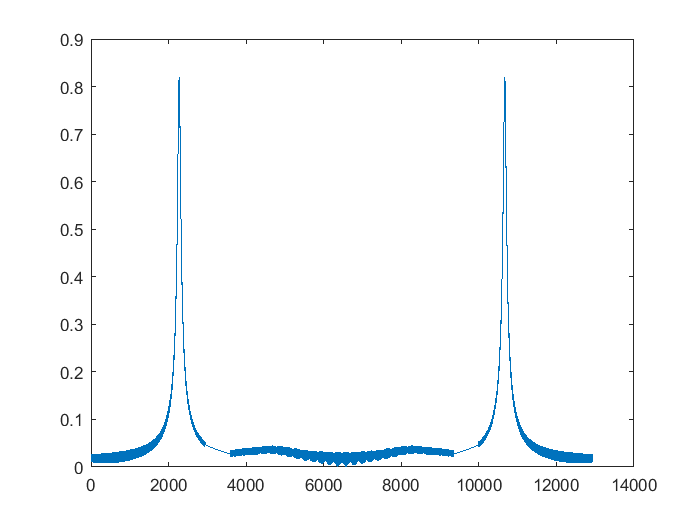

% излучаель создает магнитное поле 
k = 2*pi;
eta = 120*pi;

% падающее поле 
for m = 1 : N
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);
    
    % растояния 
    r1 = ((xm-x1_antenn)^2 + (zm-z1_antenn)^2);
    r2 = ((xm-x2_antenn)^2 + (zm-z2_antenn)^2);
    
    % Падающее магнитное поле
    H(m) = besselh(0,1,k*r1) + besselh(0,1,k*r2);
    % Касательное электрическое поле
    Ex = -1i*eta*(zm-z1_antenn)*besselh(1,1,k*r1)/r1...
         -1i*eta*(zm-z2_antenn)*besselh(1,1,k*r2)/r2;
     
    Ez = +1i*eta*(xm-x1_antenn)*besselh(1,1,k*r1)/r1...
         +1i*eta*(xm-x2_antenn)*besselh(1,1,k*r2)/r2;
     
    E(m) = Ex*txm + Ez*tzm;
end  

plot(1:N, abs(H))

Сам алгоритм расчета

% 3 - cам ходя расчета 
% списик для хранения элементов системы 
    
for m  = 1 : N
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);
    nxm = nx(m);
    nzm = nz(m);
    
    for n = 1 : N
        xn = x_midle(n);
        zn = z_midle(n);
        txn = tx(n);
        tzn = tz(n);
        nxn = nx(n);
        nzn = nz(n);
        dx = dx_mass(n);
            
        % Растояние между началом координат О2 и точкой наблюдений (в ГСК)        
        x_mO2 = xm - xn;
        z_mO2 = zm - zn;
        
        % Положим этот вектор на новую СК
        % Координаты этой точки (в ЛСК)
        umn = x_mO2*txn + z_mO2*tzn;
        wmn = x_mO2*nxn + z_mO2*nzn;
        
        % локальные замены 
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2 + zmn^2);
        
        umn_plus = umn + dx/2;
        umn_minus = umn - dx/2; 
        r_minus = sqrt(umn_minus^2 + wmn^2);
        r_plus = sqrt(umn_plus^2 + wmn^2);
        rmn = sqrt(umn^2 + wmn^2);
        
        Hus = 0;
        Hws = 0;
        
        dx = dx_mass(n); % current dx
        
        if n == m %r < 0.001*dx 
            % y - cоставляющая 
            Hys = -0.5;
            
        elseif abs(n - m) < -1.5 %r <= 2*dx
            % y - cоставляющая                     
            umn_plus_dx2 = umn + dx/2;
            umn_minus_dx2 = umn - dx/2;
            Hys = -(1i/8*wmn*k^2*dx + 1/(2*pi)*(atan(umn_plus_dx2/wmn) - atan(umn_minus_dx2/wmn)));
                 
        else 
            % y - cоставляющая
            rmn = sqrt(umn^2 + wmn^2);    
            Hys = -1i/4*k*dx*(wmn/rmn*besselh(1,1,k*rmn));  
            
        end
        
%       символ кронкера
        if m == n
            kronker = 1;
        else 
            kronker = 0;
        end
        
        % расчет матричнх элементов 
        Zmn(m,n) = kronker + Hys;
    end
end

% расчеток токов ВИ 
I=Zmn\H;

figure;
fig = plot(1:N, abs(I), 'r');
title('График распределения тока (относит. ток) - (1)'); 
xlabel('Координаты центра цилиндрика'); 
xlim([0 360])
ylabel('Плотность тока');